# Hands on 3: 1.3

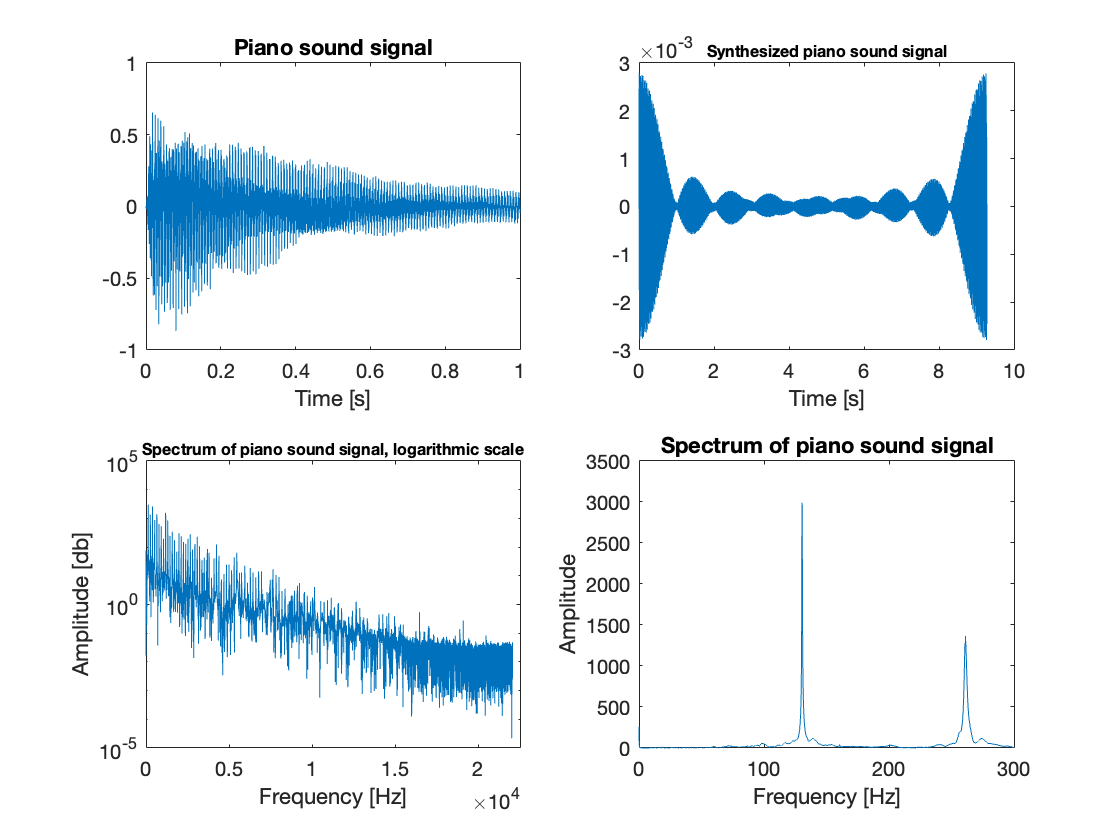

% Load data:
[y, fs]  = audioread('piano.wav');
timeVector = 0:1/fs:length(y)/fs-1/fs;

% Plot data:
hold on
subplot(2, 2, 1)
plot(timeVector, y)
xlim([0, 1])
title('Piano sound signal')
xlabel('Time [s]')
hold off

% Compute the fourier transform of the signal:
Y = fft(y);
Y = fftshift(Y);
N = length(y);
delta_f = fs/N;
freq = -fs/2:delta_f:fs/2-delta_f;

% Plot the whole spectrum of the signal:
subplot(2, 2, 3)
semilogy(freq(freq > 0), abs(Y(freq > 0)))
xlim([0, 22500])
title('Spectrum of piano sound signal, logarithmic scale', 'FontSize', 8)
xlabel('Frequency [Hz]')
ylabel('Amplitude [db]')

% Plot to find the fundamental frequency:
subplot(2, 2, 4)
plot(freq, abs(Y))
xlim([0, 300])
ylim([0, 3500])
title('Spectrum of piano sound signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

% Synthezise 
f0 = 130;
Y_syn = zeros([1, length(Y)]);

for k = 1:170
    Y_syn(round(freq) == k * f0) = 1 / (2 * 1i);
    Y_syn(round(freq) == -k * f0) = -1 / (2 * 1i);
end

% Transform back to time domain:
Y_syn = ifftshift(Y_syn);
y_syn = ifft(Y_syn);

%sound(y_syn*100, fs)

% Plot the synthesized piano signal:
hold on
subplot(2, 2, 2)
plot(timeVector, y_syn)
title('Synthesized piano sound signal', 'FontSize', 8)
%xlim([0,1])
xlabel('Time [s]')
hold off

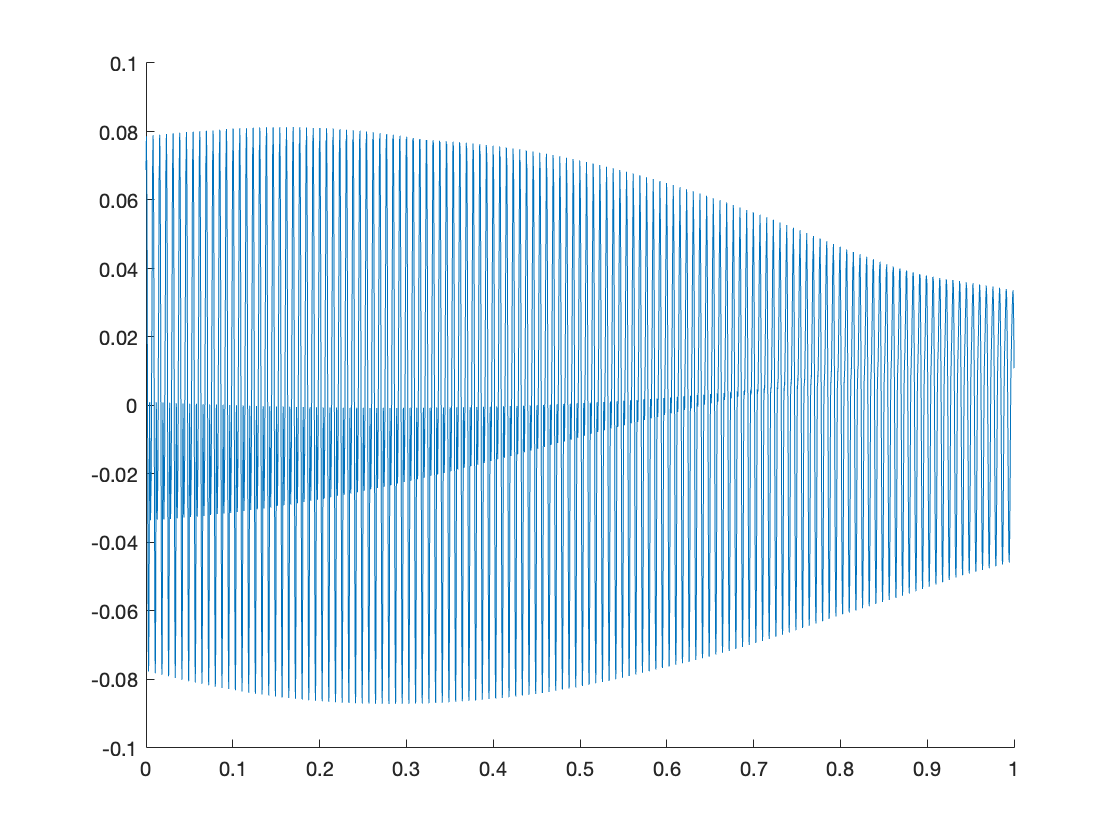


% Now synthesize including phase and amplitude:
Y_syn = zeros([1, length(Y)]);

for k = 1:170
    Y_syn(round(freq) == k * f0) = Y(round(freq) == k * f0);
    Y_syn(round(freq) == -k * f0) = Y(round(freq) == -k * f0);
end

% Transform back to time domain:
Y_syn = ifftshift(Y_syn);
y_syn = ifft(Y_syn);

sound(y_syn, fs)

figure()
hold on
plot(timeVector, y_syn)
xlim([0, 1])
hold off

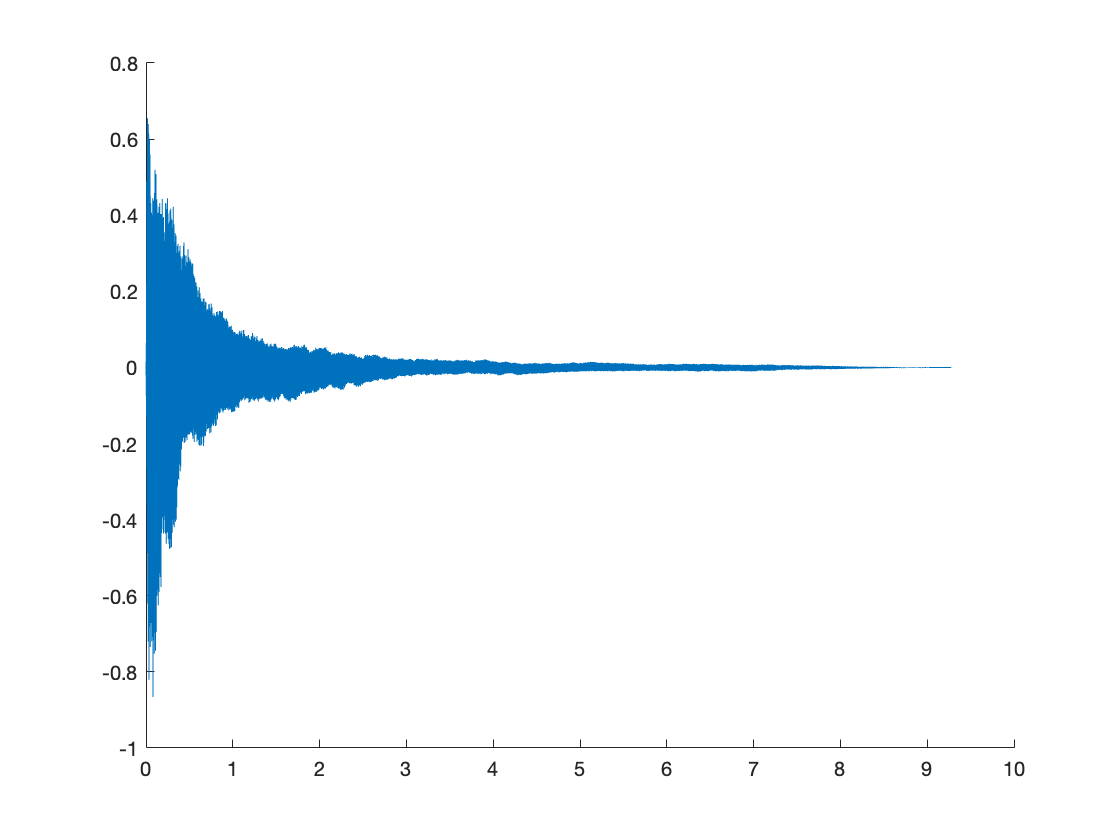


figure()
hold on
plot(timeVector, y)
hold off